clear; clc; close all;

1

matlab_solver


历时 0.016348 秒。


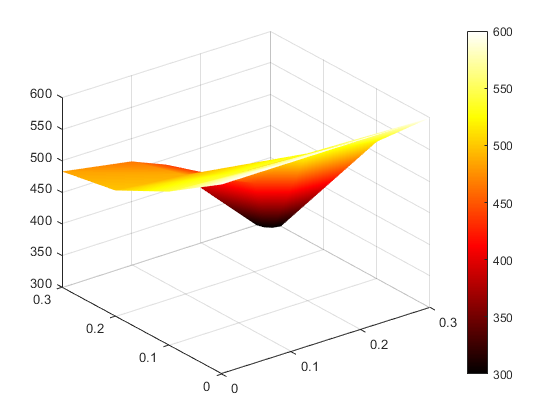

solveGauss


历时 0.011285 秒。


G_solver


历时 4.400567 秒。


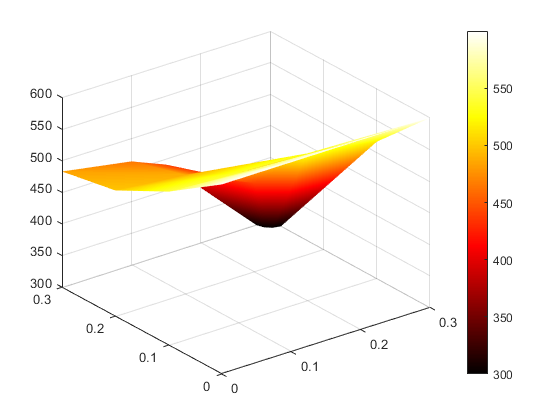

CG_solver


历时 0.019185 秒。


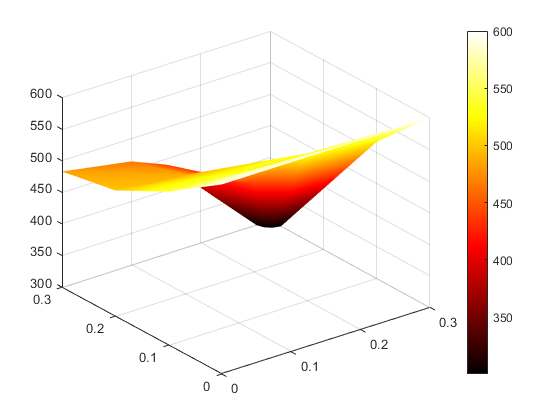

% initialize question
global lambda;
global ro;
global c;
lambda = 48;
ro = 7800;
c = 452;

timInt_m = 1; % einschritt theta
theta = 0.5;
timestep = 500;
t_star = 5000;

r = 0.02;
b = 0.3;
h = 0.3;
T0 = zeros(18,1)+300;
T1 = 600;
T2 = 300;

nodes = gen_nodes(r,b,h);
elements = [1 2 6 5
    2 3 7 6
    3 4 8 7
    5 6 10 9
    6 7 11 10
    7 12 14 11
    7 8 13 12
    9 10 16 15
    10 11 17 16
    11 14 18 17
    ];
dbc = [1 T1
    2 T1
    3 T1
    4 T1
    12 T2
    13 T2
    14 T2
    18 T2
    ];

solvers = {@matlab_solver, @solveGauss, @G_solver, @CG_solver};

for solver = solvers
    solver = solver{1};
    display(func2str(solver))
    tic
    T = solve_question(nodes,elements,dbc,0,timestep,t_star,T0,timInt_m,theta,solver);
    sol = T(:,end);
    toc
    % display solution
    figure;
    quadplot(nodes,elements,sol);
    shading interp;
    colormap hot;
    colorbar;
end

T = solve_question(nodes,elements,dbc,0,timestep,t_star,T0,timInt_m,theta,@G_solver);
num_step = size(T,2);

timestamp =11;
sol = T(:,timestamp);
quadplot(nodes,elements,sol);
shading interp;
colormap hot;
colorbar;

function nodes = gen_nodes(r,b,h)
    nodes = zeros(18,2);
    [x, y] = meshgrid(linspace(0,b,4),linspace(0,h,4));
    nodes([1:11,15:16],:) = [y([1:11,13:14])',x([1:11,13:14])'];
    nodes(12,:)=[b-r*sin(pi/6),b-r*cos(pi/6)];
    nodes(13,:)=[b,h-r];
    nodes(14,:)=[b-r*cos(pi/6),b-r*sin(pi/6)];
    nodes(17,:)=[b/2,h];
    nodes(18,:)=[b-r,h];
end

function T = solve_question(nodes,elements,dbc,start_t,timestep,end_t,T0,timInt_m,theta,solver)
    t = start_t:timestep:end_t;
    T = zeros(numel(T0),numel(t));
    T(:,1) = T0;
    n = 2;
    gpx = gx2dref(n);
    gpw = gw2dref(n);
    
    for ts=1:numel(t)-1
        sysmat = zeros(size(nodes,1));
        rhs = zeros(size(nodes,1),1);
        for i=1:size(elements,1)
            ele = elements(i,:);
            elenodes = nodes(ele,:);
            elesol = T(ele,ts);
            if ts==1
                eleosol = elesol;
            else
                eleosol = T(ele,ts-1);
            end
            [elemat,elevec] = evaluate_instat(elenodes,gpx,gpw,elesol,eleosol,timInt_m,timestep,theta,ts==1);
            [sysmat,rhs] = assemble(elemat,elevec,sysmat,rhs,ele);
        end
        [sysmat,rhs] = assignDBC(sysmat,rhs,dbc);
        % [sysmat,rhs] = assignSYM(sysmat,rhs,dbc);
        T(:,ts+1) = solver(sysmat,rhs);
    end
end

function x = matlab_solver(A,b)
    x = A\b;
end

function x = G_solver(A,b)
    x = solveG(A,b,zeros(size(b)), 1e-7, 1000000);
end

function x = CG_solver(A,b)
    x = solveCG(A,b,zeros(size(b)), 1e-7, 1000);
end

function [sysmat,rhs] = assignSYM(sysmat,rhs,dbc)
    eyes = eye(size(sysmat));
    for i=1:size(dbc,1)
        mask = true(size(rhs));
        mask(dbc(i,1)) = false;
        rhs(mask) = rhs(mask) - sysmat(mask, dbc(i,1)) .* rhs(dbc(i,1));
        sysmat(:,dbc(i,1)) = eyes(:,dbc(i,1));
    end
end

